# 'text' method usage example

Common setup for all examples

ex_setup

Setup complete


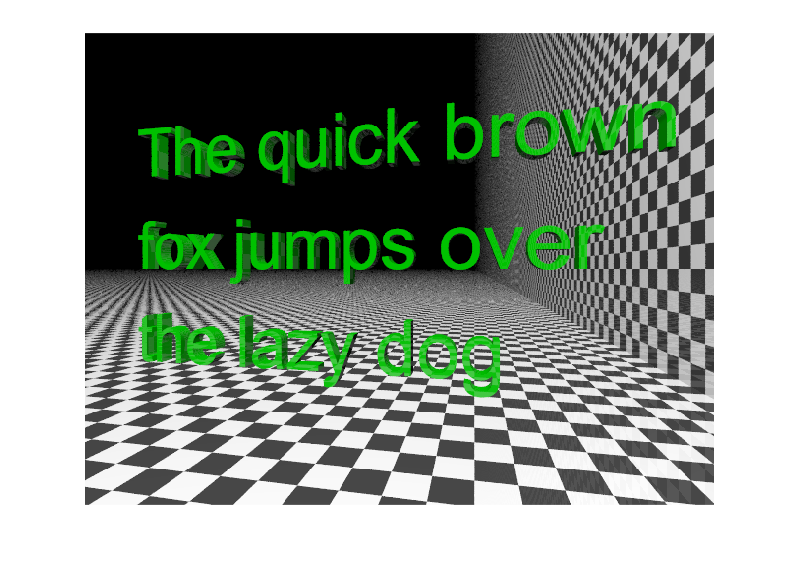

% Start timer
tic

% Povlab object
pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

pl.scene_begin('scene_file', 'text.pov', 'image_file', 'text.png');
    pl.light('location', [0 15 2], 'color', [1 1 1], 'shadowless', true);
    pl.light('location', [0 0 30], 'color', [0.7 0.7 0.7], 'shadowless', true);

    pl.camera('angle', 80, 'location', [-1 5 0], 'look_at', [0 0 0]);

    % Walls
    tex_plane  = pl.declare("tex_plane", pl.texture('pigment_odd', [1.5 1.5 1.5], 'pigment_even', [0.1 0.1 0.1]));
    pl.plane('normal', [1,0,0], 'texture', tex_plane', 'translate', [-10 0 1]);
    pl.plane('normal', [0,0,1], 'texture', tex_plane', 'translate', [0 0 -5]);
    
    % Texture
    tex_green = pl.declare('tex_green', pl.texture('pigment', [0 1.8 0], ...
                           'finish', 'ambient 0.001 diffuse 0.3 reflection 0.04 specular 24.4 roughness 0.0004'));
    pl.text('text', 'The quick brown', 'font', 'arial.ttf', 'thickness', 0.2, 'offset', 0, 'texture', tex_green ,'scale', [1 1 1], 'rotate', [90 0 180], 'translate', [4 0 1.4]);
    pl.text('text', 'fox jumps over', 'font', 'arial.ttf', 'thickness', 0.2, 'offset', 0, 'texture', tex_green ,'scale', [1 1 1], 'rotate', [90 0 180], 'translate', [4 0 0]);
    pl.text('text', 'the lazy dog', 'font', 'arial.ttf', 'thickness', 0.2, 'offset', 0, 'texture', tex_green ,'scale', [1 1 1], 'rotate', [90 0 180], 'translate', [4 0 -1.4]);
    
pl.scene_end();

% Render and display
image = pl.render();
imshow(image);

% Elapsed time
toc

Elapsed time is 2.823742 seconds.
